x_max = 55;
N_max_gr = 8;
gamma0 = 0;
gamma1 = 1;
gamma2 = 3;

x_eff = 11.8;
x_eff_real = 16;
psi = 0.96;
psi_real = 1.008;
A = [1.0075 1.0095 1.01]';
A_real = [1.0018 1.016 1.009]';
% I'm not going to bother writing out the group number bit since it will
% cancel with the 10
B = [1.65 2.07 2.47]';
B_real = [1.6969 2.2175 1.6709]';
lambda = 700;

x_con_init = [20 22 25 27 17]; 
x_aux_init = [6 6 7 7 8];

parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

parameters_pred = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff, ...
    'psi', psi, ...
    'A', A, ...
    'B', B, ...
    'lambda', lambda);


Np = 15;
parameters = parameters_real;

xk = [20;6];
[a,b,c] = functionForAll(Np, xk, parameters, 2)

U
L
U
U
U
L
U
U
U
L
U
U
U
U
U
U
U
U
U
U
U
U
U
U
L
U
U
U
U
U
U
L
U
U
U
L
U
U
U
U
U
U
U
U
U
U
U
U
L
U
L
U
L
U
L
U
L
U
L
U
L
U
L
U
L
U
L


a =      0
     0


b = 2

c = 2106

## Real 2.5

finduOpt = @(xk) functionForAll(Np, xk, parameters_pred, -1);
realUpdate = @(xk, uk) functionForAll(Np, xk, parameters_real, uk);


%[x_next, u_opt, J_opt] = realUpdate(xk, 0)

T_end = 40; 

xk = zeros(2,5, T_end + 1); % xcon/xaux, section, time
xk(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions

tic
for i = 2:T_end+1
    disp("x_k = " + num2str(xk(:,:,i-1)))
    disp("time_elapsed = " + num2str(toc) + "seconds")
    disp("time step " + num2str(i-1) + " of " + num2str(T_end))
    for j = 1:5
        [~,u_k,~] = finduOpt(xk(:,j,i-1)); 
        [xk(:,j,i), ~, ~] = realUpdate(xk(:,j,i-1), u_k);
    end
end

    "x_k = 20  22  25  27  17"
    "x_k =  6   6   7   7   8"



time_elapsed = 0.014843seconds


time step 1 of 40


    "x_k = 21.7329      23.7365      26.7419      28.7455      18.7275"
    "x_k =       6            6            7            7            8"



time_elapsed = 25.3259seconds


time step 2 of 40


    "x_k = 23.4689            0      28.4869      30.4941      20.4581"
    "x_k =       6            0            7            7            8"



time_elapsed = 47.9036seconds


time step 3 of 40


    "x_k = 0       1.6969      30.2351      33.1995      22.1918"
    "x_k = 0            0            7            7            8"



time_elapsed = 64.2462seconds


time step 4 of 40


    "x_k = 1.6969      3.39685      32.9364      17.3371            0"
    "x_k =      0            0            7            8            0"



time_elapsed = 73.748seconds


time step 5 of 40


    "x_k = 3.39685      5.09987      17.0719      19.0653       1.6969"
    "x_k =       0            0            8            8            0"



time_elapsed = 77.6969seconds


time step 6 of 40


    "x_k = 5.09987      6.80595      18.7995      20.7965      3.39685"
    "x_k =       0            0            8            8            0"



time_elapsed = 78.4034seconds


time step 7 of 40


    "x_k = 6.80595       8.5151      20.5302      22.5308      5.09987"
    "x_k =       0            0            8            8            0"



time_elapsed = 79.5945seconds


time step 8 of 40


    "x_k = 8.5151      10.2273      22.2641            0      6.80595"
    "x_k =      0            0            8            0            0"



time_elapsed = 81.0924seconds


time step 9 of 40


    "x_k = 10.2273      11.9426            0       1.6969       8.5151"
    "x_k =       0            0            0            0            0"



time_elapsed = 83.5773seconds


time step 10 of 40


    "x_k = 11.9426       13.661       1.6969      3.39685      10.2273"
    "x_k =       0            0            0            0            0"



time_elapsed = 87.2888seconds


time step 11 of 40


    "x_k = 13.661      15.3825      3.39685      5.09987      11.9426"
    "x_k =      0            0            0            0            0"



time_elapsed = 92.1364seconds


time step 12 of 40


    "x_k = 15.3825      17.1071      5.09987      6.80595       13.661"
    "x_k =       0            0            0            0            0"



time_elapsed = 98.0884seconds


time step 13 of 40


    "x_k = 17.1071      18.8348      6.80595       8.5151      15.3825"
    "x_k =       0            0            0            0            0"



time_elapsed = 103.4782seconds


time step 14 of 40


    "x_k = 18.8348      20.5656       8.5151      10.2273      17.1071"
    "x_k =       0            0            0            0            0"



time_elapsed = 111.2827seconds


time step 15 of 40


    "x_k = 20.5656      22.2995      10.2273      11.9426      18.8348"
    "x_k =       0            0            0            0            0"



time_elapsed = 122.6074seconds


time step 16 of 40


    "x_k = 22.2995      24.0366      11.9426       13.661      20.5656"
    "x_k =       0            0            0            0            0"



time_elapsed = 141.2564seconds


time step 17 of 40


    "x_k = 24.0366      25.7767       13.661      15.3825      22.2995"
    "x_k =       0            0            0            0            0"



time_elapsed = 165.7923seconds


time step 18 of 40


    "x_k = 25.7767        27.52      15.3825      17.1071      24.0366"
    "x_k =       0            0            0            0            0"



time_elapsed = 194.5325seconds


time step 19 of 40


    "x_k = 27.52      29.2665      17.1071      18.8348      25.7767"
    "x_k =     0            0            0            0            0"



time_elapsed = 225.0134seconds


time step 20 of 40


    "x_k = 29.2665       31.016      18.8348      20.5656        27.52"
    "x_k =       0            0            0            0            0"



time_elapsed = 257.8875seconds


time step 21 of 40


    "x_k = 31.016      33.7298      20.5656      22.2995      29.2665"
    "x_k =      0            0            0            0            0"



time_elapsed = 295.1276seconds


time step 22 of 40


    "x_k = 33.7298      17.8716      22.2995      24.0366       31.016"
    "x_k =       0            1            0            0            0"



time_elapsed = 336.1175seconds


time step 23 of 40


    "x_k = 17.8716      19.6007      24.0366      25.7767      33.7298"
    "x_k =       1            1            0            0            0"



time_elapsed = 371.6607seconds


time step 24 of 40


## Real 2.6

function totalCost = doMe(var)
    x_max = 38;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [0;0];
    parameters_real.N_max_gr = N_gr;
    Np = 8;
    T_end = 20; 
    IDs = 1:M:T_end; u = zeros(1,T_end); u(IDs) = 1;
    totalCost = 0;
    for i = 1:T_end
        [xk,~,J] = functionForAll(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        if(xk(2) >= N_gr)
            u(i+1) = 2;
        end
    end 
end
tic
LB = [0,0]; UB = [19, 19];
doMeNow = @doMe;
N_M = ga(doMeNow, 2, zeros(1,2), 0, zeros(1,2) ,0, LB, UB); % took 25 minutes to run, game N_max = 0.54, M = 1.8339

     0

     0

       40600

        2100

        1400

       40600

        2100

     0

        1400

        1400

     0

     0

        7000

       40600

       40600

     0

        1400

       40600

     0

       40600

     0

        1400

     0

        3500

        2800

     0

        7000

   700

        1400

        7000

        1400

     0

     0

        3500

     0

        1400

     0

     0

     0

     0

        1400

     0

        1400

     0

     0

     0

        2800

        1400

        2100

     0

     0

     0

     0

     0

       10500

        1400

        4900

        1400

     0

        2100

        7000

        1400

       13300

   700

     0

       11200

        7000

        3500

        1400

        2100

     0

        2100

        7000

        9800

       13300

     0

        1400

        7000

        2100

     0

     0

     0

        1400

     0

        4900

        6300

        1400

N_max_gr = N_M(1);
M = N_M(2);
time = toc;




## testing

function [x, us, totalCost] = doMe2(var)
    x_max = 38;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [0;0];
    parameters_real.N_max_gr = N_gr;
    Np = 1;
    T_end = 20; 
    IDs = 1:M:T_end; u = zeros(1,T_end); u(IDs) = 1;
    totalCost = 0;
    x = zeros(2,T_end);
    us = zeros(1,T_end);
    for i = 1:T_end
        [xk,u_current,J] = functionForAll(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        x(:,i) = xk; us(i) = u_current;
        if(xk(2) >= N_gr)
            u(i+1) = 2;
        end
    end 
end

[xs, us, J] = doMe2([19; 19])

xs =          0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610   15.3825   17.1071   18.8348   20.5656   22.2995   24.0366   25.7767   27.5200   29.2665   31.0160   33.7298   36.4870   39.2883   42.1344   45.0260   47.9639   50.9489   53.0783   55.2269   57.3949   59.5823   61.7895   64.0165   66.2635   68.5308   70.8185         0    1.6969    3.3969    5.0999    6.8059
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0


us =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


J = 700

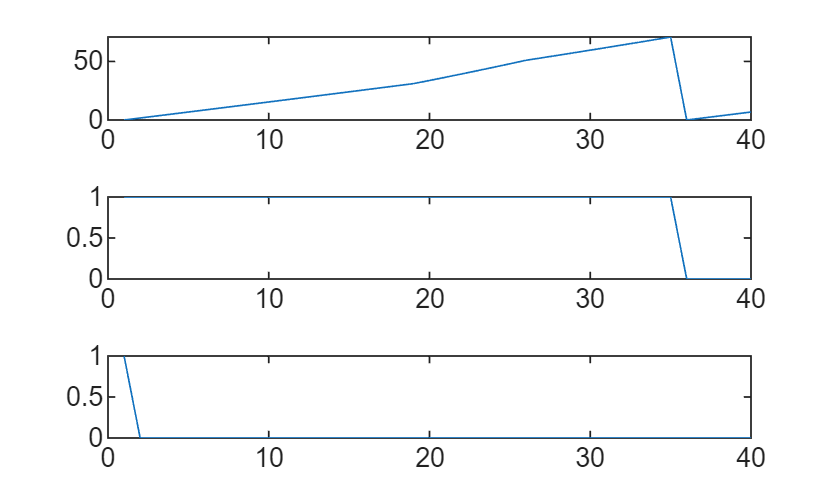


N = size(xs,2);
tiledlayout(3,1)
nexttile
plot(1:N, xs(1,:));
nexttile
plot(1:N, xs(2,:));
nexttile
plot(1:N, us(:));